%{
radial clearance
axial clearance
coil h
coil r in
coil r out
wire diameter
coil former radial t
coil former axial t
mag bot axial t
mag top axial t
armature r
chamfer r
chamfer h
shell t
packing ratio
current safety factor
air gap
relative permeability
permeability
copper wire current capacity
%}
close all
clear
syms c_r c_a h_C r_Cout D_w t_cfr t_cfa t_mba t_mta...
    r_A r_cham h_cham t_shell PR CSF h_air mu mu0 CWCC I

magnetic_top_r = t_shell + r_Cout + c_r

$$magnetic\_top\_r = c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}$$

r_Cin = r_A + c_r + t_cfr

$$r\_Cin = c_{r}+r_{A}+t_{\mathrm{cfr}}$$

R_path1 = r_Cout / (mu * mu0 * t_mta * pi * 0.25 * (magnetic_top_r + r_Cout + c_a))

$$R\_path1 = \frac{4\,r_{\mathrm{Cout}}}{\mu \,\mu_{0}\,t_{\mathrm{mta}}\,\pi \,\left(c_{a}+c_{r}+2\,r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}$$

h_coilformer = h_C + 2 * t_cfa

$$h\_coilformer = h_{C}+2\,t_{\mathrm{cfa}}$$

shell_rin = r_Cout + c_r

$$shell\_rin = c_{r}+r_{\mathrm{Cout}}$$

shell_rout = magnetic_top_r

$$shell\_rout = c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}$$

R_path2_a = (t_mta + h_coilformer + t_mba / 2 - c_a) /...
    (mu * mu0 * pi * (magnetic_top_r^2 - shell_rin^2))

$$R\_path2\_a = \frac{h_{C}-c_{a}+2\,t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}+t_{\mathrm{mta}}}{\mu \,\mu_{0}\,\pi \,\left({\left(c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}^{2}-{\left(c_{r}+r_{\mathrm{Cout}}\right)}^{2}\right)}$$

    
R_path2_b = c_a / (mu0 *pi * (magnetic_top_r^2 - shell_rin^2))

$$R\_path2\_b = \frac{c_{a}}{\mu_{0}\,\pi \,\left({\left(c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}^{2}-{\left(c_{r}+r_{\mathrm{Cout}}\right)}^{2}\right)}$$

R_path2 = R_path2_a + R_path2_b

$$R\_path2 = \frac{c_{a}}{\mu_{0}\,\pi \,\left({\left(c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}^{2}-{\left(c_{r}+r_{\mathrm{Cout}}\right)}^{2}\right)}+\frac{h_{C}-c_{a}+2\,t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}+t_{\mathrm{mta}}}{\mu \,\mu_{0}\,\pi \,\left({\left(c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}^{2}-{\left(c_{r}+r_{\mathrm{Cout}}\right)}^{2}\right)}$$

R_path3_a = 0.5 * t_shell /...
    (mu * mu0 * t_mba * pi * (shell_rin + t_shell * 0.5))

$$R\_path3\_a = \frac{t_{\mathrm{shell}}}{2\,\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{\mathrm{Cout}}+\frac{t_{\mathrm{shell}}}{2}\right)}$$

R_path3_b = c_r / (mu0 * t_mba * pi * (shell_rin - 0.5 * c_r))

$$R\_path3\_b = \frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{\mathrm{Cout}}\right)}$$

R_path3_c = (r_Cout - (r_A + c_r)) /...
        (mu * mu0 * t_mba * pi * 0.5 * ((r_A + c_r) + r_Cout))

$$R\_path3\_c = -\frac{2\,\left(c_{r}+r_{A}-r_{\mathrm{Cout}}\right)}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{A}+r_{\mathrm{Cout}}\right)}$$

R_path3_d = c_r / (mu0 * t_mba * pi * (r_A + 0.5 * c_r))

$$R\_path3\_d = \frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{A}\right)}$$

R_path3_e = r_A / (mu * mu0 * t_mba * pi * 0.5 * r_A)

$$R\_path3\_e = \frac{2}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi }$$


R_path3 = R_path3_a + R_path3_b + R_path3_c + R_path3_d + R_path3_e

$$R\_path3 = \frac{2}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi }+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{A}\right)}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{\mathrm{Cout}}\right)}+\frac{t_{\mathrm{shell}}}{2\,\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{\mathrm{Cout}}+\frac{t_{\mathrm{shell}}}{2}\right)}-\frac{2\,\left(c_{r}+r_{A}-r_{\mathrm{Cout}}\right)}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{A}+r_{\mathrm{Cout}}\right)}$$

theta = atan(h_cham / r_cham)

$$theta = \mathrm{atan}\left(\frac{h_{\mathrm{cham}}}{r_{\mathrm{cham}}}\right)$$

R_path4_a = (0.5 * (h_coilformer + t_mba) + c_a - h_air) /...
    (mu * mu0 * pi * r_A^2)

$$R\_path4\_a = \frac{c_{a}+\frac{h_{C}}{2}-h_{\mathrm{air}}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}}{\mu \,\mu_{0}\,{r_{A}}^{2}\,\pi }$$

R_path4_b_1 = h_air / (mu0 * pi * (r_A - r_cham)^2)

$$R\_path4\_b\_1 = \frac{h_{\mathrm{air}}}{\mu_{0}\,\pi \,{\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}}$$

R_path4_b_2 = (h_air * cos(theta)) / (mu0 * pi * (r_A^2 - (r_A - r_cham)^2)/cos(theta))

$$R\_path4\_b\_2 = -\frac{h_{\mathrm{air}}}{\mu_{0}\,\pi \,\left(\frac{{h_{\mathrm{cham}}}^{2}}{{r_{\mathrm{cham}}}^{2}}+1\right)\,\left({\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}-{r_{A}}^{2}\right)}$$

R_path4_b = 1 / (1/R_path4_b_1 + 1/R_path4_b_2)

$$R\_path4\_b = \frac{1}{\frac{\pi \,\mu_{0}\,{\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}}{h_{\mathrm{air}}}-\frac{\pi \,\mu_{0}\,\left(\frac{{h_{\mathrm{cham}}}^{2}}{{r_{\mathrm{cham}}}^{2}}+1\right)\,\left({\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}-{r_{A}}^{2}\right)}{h_{\mathrm{air}}}}$$

% Compute simplified symbolic expression
simplifiedExpr = simplify(R_path4_b)

$$simplifiedExpr = \frac{h_{\mathrm{air}}\,r_{\mathrm{cham}}}{\mu_{0}\,\pi \,\left(2\,{h_{\mathrm{cham}}}^{2}\,r_{A}-r_{\mathrm{cham}}\,{h_{\mathrm{cham}}}^{2}+r_{\mathrm{cham}}\,{r_{A}}^{2}\right)}$$

R_path4_c = (0.5 * (h_coilformer + t_mta) + c_a) /...
    (mu * mu0 * pi * r_A^2)

$$R\_path4\_c = \frac{c_{a}+\frac{h_{C}}{2}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mta}}}{2}}{\mu \,\mu_{0}\,{r_{A}}^{2}\,\pi }$$

R_path4 = R_path4_a + R_path4_b + R_path4_c

$$R\_path4 = \frac{1}{\frac{\pi \,\mu_{0}\,{\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}}{h_{\mathrm{air}}}-\frac{\pi \,\mu_{0}\,\left(\frac{{h_{\mathrm{cham}}}^{2}}{{r_{\mathrm{cham}}}^{2}}+1\right)\,\left({\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}-{r_{A}}^{2}\right)}{h_{\mathrm{air}}}}+\frac{c_{a}+\frac{h_{C}}{2}-h_{\mathrm{air}}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}}{\mu \,\mu_{0}\,{r_{A}}^{2}\,\pi }+\frac{c_{a}+\frac{h_{C}}{2}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mta}}}{2}}{\mu \,\mu_{0}\,{r_{A}}^{2}\,\pi }$$

R_total = R_path1 + R_path2 + R_path3 + R_path4

$$R\_total = \begin{array}{l} \frac{1}{\frac{\pi \,\mu_{0}\,{\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}}{h_{\mathrm{air}}}-\frac{\pi \,\mu_{0}\,\left(\frac{{h_{\mathrm{cham}}}^{2}}{{r_{\mathrm{cham}}}^{2}}+1\right)\,\left({\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}-{r_{A}}^{2}\right)}{h_{\mathrm{air}}}}+\frac{2}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi }+\frac{c_{a}}{\mu_{0}\,\pi \,\sigma_{1}}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{A}\right)}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{\mathrm{Cout}}\right)}+\frac{h_{C}-c_{a}+2\,t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}+t_{\mathrm{mta}}}{\mu \,\mu_{0}\,\pi \,\sigma_{1}}+\frac{c_{a}+\frac{h_{C}}{2}-h_{\mathrm{air}}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}}{\sigma_{2}}+\frac{c_{a}+\frac{h_{C}}{2}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mta}}}{2}}{\sigma_{2}}+\frac{t_{\mathrm{shell}}}{2\,\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{\mathrm{Cout}}+\frac{t_{\mathrm{shell}}}{2}\right)}-\frac{2\,\left(c_{r}+r_{A}-r_{\mathrm{Cout}}\right)}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{A}+r_{\mathrm{Cout}}\right)}+\frac{4\,r_{\mathrm{Cout}}}{\mu \,\mu_{0}\,t_{\mathrm{mta}}\,\pi \,\left(c_{a}+c_{r}+2\,r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}\\ \mathrm{where}\\ \sigma_{1}={\left(c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}^{2}-{\left(c_{r}+r_{\mathrm{Cout}}\right)}^{2}\\ \sigma_{2}=\mu \,\mu_{0}\,{r_{A}}^{2}\,\pi \end{array}$$

func_R_total = matlabFunction(R_total)

func_R_total = function_handle with value:
    @(c_a,c_r,h_C,h_air,h_cham,mu,mu0,r_A,r_Cout,r_cham,t_cfa,t_mba,t_mta,t_shell)1.0./((mu0.*pi.*(r_A-r_cham).^2)./h_air-(mu0.*pi.*(h_cham.^2.*1.0./r_cham.^2+1.0).*((r_A-r_cham).^2-r_A.^2))./h_air)+2.0./(mu.*mu0.*t_mba.*pi)+c_a./(mu0.*pi.*((c_r+r_Cout+t_shell).^2-(c_r+r_Cout).^2))+c_r./(mu0.*t_mba.*pi.*(c_r./2.0+r_A))+c_r./(mu0.*t_mba.*pi.*(c_r./2.0+r_Cout))+(-c_a+h_C+t_cfa.*2.0+t_mba./2.0+t_mta)./(mu.*mu0.*pi.*((c_r+r_Cout+t_shell).^2-(c_r+r_Cout).^2))+(1.0./r_A.^2.*(c_a+h_C./2.0-h_air+t_cfa+t_mba./2.0))./(mu.*mu0.*pi)+(1.0./r_A.^2.*(c_a+h_C./2.0+t_cfa+t_mta./2.0))./(mu.*mu0.*pi)+t_shell./(mu.*mu0.*t_mba.*pi.*(c_r+r_Cout+t_shell./2.0).*2.0)-((c_r+r_A-r_Cout).*2.0)./(mu.*mu0.*t_mba.*pi.*(c_r+r_A+r_Cout))+(r_Cout.*4.0)./(mu.*mu0.*t_mta.*pi.*(c_a+c_r+r_Cout.*2.0+t_shell))


A_w = D_w^2 * pi * 0.25

$$A\_w = \frac{\pi \,{D_{w}}^{2}}{4}$$

N = h_C/D_w * (r_Cout - r_Cin)/D_w * PR

$$N = -\frac{\mathrm{PR}\,h_{C}\,\left(c_{r}+r_{A}-r_{\mathrm{Cout}}+t_{\mathrm{cfr}}\right)}{{D_{w}}^{2}}$$

func_N = matlabFunction(N)

func_N = function_handle with value:
    @(D_w,PR,c_r,h_C,r_A,r_Cout,t_cfr)-1.0./D_w.^2.*PR.*h_C.*(c_r+r_A-r_Cout+t_cfr)


I_max = CWCC * A_w * CSF

$$I\_max = \frac{\pi \,\mathrm{CSF}\,\mathrm{CWCC}\,{D_{w}}^{2}}{4}$$

func_I_max = matlabFunction(I_max)

func_I_max = function_handle with value:
    @(CSF,CWCC,D_w)(CSF.*CWCC.*D_w.^2.*pi)./4.0


func_I_max(0.8,10E6,0.26E-3)

ans = 0.4247

NI = N * I

$$NI = -\frac{\text{I}\,\mathrm{PR}\,h_{C}\,\left(c_{r}+r_{A}-r_{\mathrm{Cout}}+t_{\mathrm{cfr}}\right)}{{D_{w}}^{2}}$$

double(subs(NI,...
    [D_w,    I,                           PR,  c_r,    h_C,  r_A,    r_Cout,t_cfr],...
    [0.26E-3,func_I_max(0.8,10E6,0.26E-3),0.95,0.05E-3,50E-3,4.95E-3,15E-3, 1.5E-3]))

ans = 2.5368e+03

phi = NI / R_total

$$phi = \begin{array}{l} -\frac{\text{I}\,\mathrm{PR}\,h_{C}\,\left(c_{r}+r_{A}-r_{\mathrm{Cout}}+t_{\mathrm{cfr}}\right)}{{D_{w}}^{2}\,\left(\frac{1}{\frac{\pi \,\mu_{0}\,{\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}}{h_{\mathrm{air}}}-\frac{\pi \,\mu_{0}\,\left(\frac{{h_{\mathrm{cham}}}^{2}}{{r_{\mathrm{cham}}}^{2}}+1\right)\,\left({\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}-{r_{A}}^{2}\right)}{h_{\mathrm{air}}}}+\frac{2}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi }+\frac{c_{a}}{\mu_{0}\,\pi \,\sigma_{1}}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{A}\right)}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{\mathrm{Cout}}\right)}+\frac{h_{C}-c_{a}+2\,t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}+t_{\mathrm{mta}}}{\mu \,\mu_{0}\,\pi \,\sigma_{1}}+\frac{c_{a}+\frac{h_{C}}{2}-h_{\mathrm{air}}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}}{\sigma_{2}}+\frac{c_{a}+\frac{h_{C}}{2}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mta}}}{2}}{\sigma_{2}}+\frac{t_{\mathrm{shell}}}{2\,\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{\mathrm{Cout}}+\frac{t_{\mathrm{shell}}}{2}\right)}-\frac{2\,\left(c_{r}+r_{A}-r_{\mathrm{Cout}}\right)}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{A}+r_{\mathrm{Cout}}\right)}+\frac{4\,r_{\mathrm{Cout}}}{\mu \,\mu_{0}\,t_{\mathrm{mta}}\,\pi \,\left(c_{a}+c_{r}+2\,r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}\right)}\\ \mathrm{where}\\ \sigma_{1}={\left(c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}^{2}-{\left(c_{r}+r_{\mathrm{Cout}}\right)}^{2}\\ \sigma_{2}=\mu \,\mu_{0}\,{r_{A}}^{2}\,\pi \end{array}$$

func_phi = matlabFunction(phi)

func_phi = function_handle with value:
    @(D_w,I,PR,c_a,c_r,h_C,h_air,h_cham,mu,mu0,r_A,r_Cout,r_cham,t_cfa,t_cfr,t_mba,t_mta,t_shell)-(1.0./D_w.^2.*I.*PR.*h_C.*(c_r+r_A-r_Cout+t_cfr))./(1.0./((mu0.*pi.*(r_A-r_cham).^2)./h_air-(mu0.*pi.*(h_cham.^2.*1.0./r_cham.^2+1.0).*((r_A-r_cham).^2-r_A.^2))./h_air)+2.0./(mu.*mu0.*t_mba.*pi)+c_a./(mu0.*pi.*((c_r+r_Cout+t_shell).^2-(c_r+r_Cout).^2))+c_r./(mu0.*t_mba.*pi.*(c_r./2.0+r_A))+c_r./(mu0.*t_mba.*pi.*(c_r./2.0+r_Cout))+(-c_a+h_C+t_cfa.*2.0+t_mba./2.0+t_mta)./(mu.*mu0.*pi.*((c_r+r_Cout+t_shell).^2-(c_r+r_Cout).^2))+(1.0./r_A.^2.*(c_a+h_C./2.0-h_air+t_cfa+t_mba./2.0))./(mu.*mu0.*pi)+(1.0./r_A.^2.*(c_a+h_C./2.0+t_cfa+t_mta./2.0))./(mu.*mu0.*pi)+t_shell./(mu.*mu0.*t_mba.*pi.*(c_r+r_Cout+t_shell./2.0).*2.0)-((c_r+r_A-r_Cout).*2.0)./(mu.*mu0.*t_mba.*pi.*(c_r+r_A+r_Cout))+(r_Cout.*4.0)./(mu.*mu0.*t_mta.*pi.*(c_a+c_r+r_Cout.*2.0+t_shell)))


H = NI / h_C

$$H = -\frac{\text{I}\,\mathrm{PR}\,\left(c_{r}+r_{A}-r_{\mathrm{Cout}}+t_{\mathrm{cfr}}\right)}{{D_{w}}^{2}}$$

func_H = matlabFunction(H)

func_H = function_handle with value:
    @(D_w,I,PR,c_r,r_A,r_Cout,t_cfr)-1.0./D_w.^2.*I.*PR.*(c_r+r_A-r_Cout+t_cfr)



T = phi / (pi * r_A^2)

$$T = \begin{array}{l} -\frac{\text{I}\,\mathrm{PR}\,h_{C}\,\left(c_{r}+r_{A}-r_{\mathrm{Cout}}+t_{\mathrm{cfr}}\right)}{{D_{w}}^{2}\,{r_{A}}^{2}\,\pi \,\left(\frac{1}{\frac{\pi \,\mu_{0}\,{\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}}{h_{\mathrm{air}}}-\frac{\pi \,\mu_{0}\,\left(\frac{{h_{\mathrm{cham}}}^{2}}{{r_{\mathrm{cham}}}^{2}}+1\right)\,\left({\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}-{r_{A}}^{2}\right)}{h_{\mathrm{air}}}}+\frac{2}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi }+\frac{c_{a}}{\mu_{0}\,\pi \,\sigma_{1}}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{A}\right)}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{\mathrm{Cout}}\right)}+\frac{h_{C}-c_{a}+2\,t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}+t_{\mathrm{mta}}}{\mu \,\mu_{0}\,\pi \,\sigma_{1}}+\frac{c_{a}+\frac{h_{C}}{2}-h_{\mathrm{air}}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}}{\sigma_{2}}+\frac{c_{a}+\frac{h_{C}}{2}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mta}}}{2}}{\sigma_{2}}+\frac{t_{\mathrm{shell}}}{2\,\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{\mathrm{Cout}}+\frac{t_{\mathrm{shell}}}{2}\right)}-\frac{2\,\left(c_{r}+r_{A}-r_{\mathrm{Cout}}\right)}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{A}+r_{\mathrm{Cout}}\right)}+\frac{4\,r_{\mathrm{Cout}}}{\mu \,\mu_{0}\,t_{\mathrm{mta}}\,\pi \,\left(c_{a}+c_{r}+2\,r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}\right)}\\ \mathrm{where}\\ \sigma_{1}={\left(c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}^{2}-{\left(c_{r}+r_{\mathrm{Cout}}\right)}^{2}\\ \sigma_{2}=\mu \,\mu_{0}\,{r_{A}}^{2}\,\pi \end{array}$$

func_T = matlabFunction(T)

func_T = function_handle with value:
    @(D_w,I,PR,c_a,c_r,h_C,h_air,h_cham,mu,mu0,r_A,r_Cout,r_cham,t_cfa,t_cfr,t_mba,t_mta,t_shell)-(1.0./D_w.^2.*I.*PR.*h_C.*1.0./r_A.^2.*(c_r+r_A-r_Cout+t_cfr))./(pi.*(1.0./((mu0.*pi.*(r_A-r_cham).^2)./h_air-(mu0.*pi.*(h_cham.^2.*1.0./r_cham.^2+1.0).*((r_A-r_cham).^2-r_A.^2))./h_air)+2.0./(mu.*mu0.*t_mba.*pi)+c_a./(mu0.*pi.*((c_r+r_Cout+t_shell).^2-(c_r+r_Cout).^2))+c_r./(mu0.*t_mba.*pi.*(c_r./2.0+r_A))+c_r./(mu0.*t_mba.*pi.*(c_r./2.0+r_Cout))+(-c_a+h_C+t_cfa.*2.0+t_mba./2.0+t_mta)./(mu.*mu0.*pi.*((c_r+r_Cout+t_shell).^2-(c_r+r_Cout).^2))+(1.0./r_A.^2.*(c_a+h_C./2.0-h_air+t_cfa+t_mba./2.0))./(mu.*mu0.*pi)+(1.0./r_A.^2.*(c_a+h_C./2.0+t_cfa+t_mta./2.0))./(mu.*mu0.*pi)+t_shell./(mu.*mu0.*t_mba.*pi.*(c_r+r_Cout+t_shell./2.0).*2.0)-((c_r+r_A-r_Cout).*2.0)./(mu.*mu0.*t_mba.*pi.*(c_r+r_A+r_Cout))+(r_Cout.*4.0)./(mu.*mu0.*t_mta.*pi.*(c_a+c_r+r_Cout.*2.0+t_shell))))



Fmag_1 = 0.5 * (phi * R_path4_b_2/(R_path4_b_1 + R_path4_b_2))^2 /...
    (mu0 * pi * (r_A - r_cham)^2)

$$Fmag\_1 = \begin{array}{l} \frac{{\text{I}}^{2}\,{\mathrm{PR}}^{2}\,{h_{C}}^{2}\,{h_{\mathrm{air}}}^{2}\,{\left(c_{r}+r_{A}-r_{\mathrm{Cout}}+t_{\mathrm{cfr}}\right)}^{2}}{2\,{D_{w}}^{4}\,{\mu_{0}}^{3}\,\pi^{3}\,{\sigma_{2}}^{2}\,{\sigma_{1}}^{2}\,{\left(\frac{h_{\mathrm{air}}}{\mu_{0}\,\pi \,{\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}}-\frac{h_{\mathrm{air}}}{\mu_{0}\,\pi \,\sigma_{2}\,\sigma_{1}}\right)}^{2}\,{\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}\,{\left(\frac{1}{\frac{\pi \,\mu_{0}\,{\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}}{h_{\mathrm{air}}}-\frac{\pi \,\mu_{0}\,\sigma_{2}\,\sigma_{1}}{h_{\mathrm{air}}}}+\frac{2}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi }+\frac{c_{a}}{\mu_{0}\,\pi \,\sigma_{3}}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{A}\right)}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{\mathrm{Cout}}\right)}+\frac{h_{C}-c_{a}+2\,t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}+t_{\mathrm{mta}}}{\mu \,\mu_{0}\,\pi \,\sigma_{3}}+\frac{c_{a}+\frac{h_{C}}{2}-h_{\mathrm{air}}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}}{\sigma_{4}}+\frac{c_{a}+\frac{h_{C}}{2}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mta}}}{2}}{\sigma_{4}}+\frac{t_{\mathrm{shell}}}{2\,\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{\mathrm{Cout}}+\frac{t_{\mathrm{shell}}}{2}\right)}-\frac{2\,\left(c_{r}+r_{A}-r_{\mathrm{Cout}}\right)}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{A}+r_{\mathrm{Cout}}\right)}+\frac{4\,r_{\mathrm{Cout}}}{\mu \,\mu_{0}\,t_{\mathrm{mta}}\,\pi \,\left(c_{a}+c_{r}+2\,r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}={\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}-{r_{A}}^{2}\\ \sigma_{2}=\frac{{h_{\mathrm{cham}}}^{2}}{{r_{\mathrm{cham}}}^{2}}+1\\ \sigma_{3}={\left(c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}^{2}-{\left(c_{r}+r_{\mathrm{Cout}}\right)}^{2}\\ \sigma_{4}=\mu \,\mu_{0}\,{r_{A}}^{2}\,\pi \end{array}$$


Fmag_2 = 0.5 * cos(theta) * (phi * R_path4_b_1/(R_path4_b_1 + R_path4_b_2))^2 /...
    (mu0 * pi * (r_A^2 - r_cham^2)/cos(theta))

$$Fmag\_2 = \begin{array}{l} \frac{{\text{I}}^{2}\,{\mathrm{PR}}^{2}\,{h_{C}}^{2}\,{h_{\mathrm{air}}}^{2}\,{\left(c_{r}+r_{A}-r_{\mathrm{Cout}}+t_{\mathrm{cfr}}\right)}^{2}}{2\,{D_{w}}^{4}\,{\mu_{0}}^{3}\,\pi^{3}\,\sigma_{1}\,\left({r_{A}}^{2}-{r_{\mathrm{cham}}}^{2}\right)\,{\left(\frac{h_{\mathrm{air}}}{\mu_{0}\,\pi \,{\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}}-\frac{h_{\mathrm{air}}}{\mu_{0}\,\pi \,\sigma_{1}\,\sigma_{3}}\right)}^{2}\,{\left(r_{A}-r_{\mathrm{cham}}\right)}^{4}\,{\left(\frac{1}{\frac{\pi \,\mu_{0}\,{\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}}{h_{\mathrm{air}}}-\frac{\pi \,\mu_{0}\,\sigma_{1}\,\sigma_{3}}{h_{\mathrm{air}}}}+\frac{2}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi }+\frac{c_{a}}{\mu_{0}\,\pi \,\sigma_{2}}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{A}\right)}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{\mathrm{Cout}}\right)}+\frac{h_{C}-c_{a}+2\,t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}+t_{\mathrm{mta}}}{\mu \,\mu_{0}\,\pi \,\sigma_{2}}+\frac{c_{a}+\frac{h_{C}}{2}-h_{\mathrm{air}}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}}{\sigma_{4}}+\frac{c_{a}+\frac{h_{C}}{2}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mta}}}{2}}{\sigma_{4}}+\frac{t_{\mathrm{shell}}}{2\,\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{\mathrm{Cout}}+\frac{t_{\mathrm{shell}}}{2}\right)}-\frac{2\,\left(c_{r}+r_{A}-r_{\mathrm{Cout}}\right)}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{A}+r_{\mathrm{Cout}}\right)}+\frac{4\,r_{\mathrm{Cout}}}{\mu \,\mu_{0}\,t_{\mathrm{mta}}\,\pi \,\left(c_{a}+c_{r}+2\,r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}=\frac{{h_{\mathrm{cham}}}^{2}}{{r_{\mathrm{cham}}}^{2}}+1\\ \sigma_{2}={\left(c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}^{2}-{\left(c_{r}+r_{\mathrm{Cout}}\right)}^{2}\\ \sigma_{3}={\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}-{r_{A}}^{2}\\ \sigma_{4}=\mu \,\mu_{0}\,{r_{A}}^{2}\,\pi \end{array}$$

Fmag = Fmag_1 + Fmag_2

func_Fmag = matlabFunction(Fmag)

func_Fmag = function_handle with value:
    @(D_w,I,PR,c_a,c_r,h_C,h_air,h_cham,mu,mu0,r_A,r_Cout,r_cham,t_cfa,t_cfr,t_mba,t_mta,t_shell)(1.0./D_w.^4.*I.^2.*PR.^2.*h_C.^2.*h_air.^2.*1.0./mu0.^3.*1.0./pi.^3.*1.0./((h_air.*1.0./(r_A-r_cham).^2)./(mu0.*pi)-h_air./(mu0.*pi.*(h_cham.^2.*1.0./r_cham.^2+1.0).*((r_A-r_cham).^2-r_A.^2))).^2.*1.0./(r_A-r_cham).^4.*(c_r+r_A-r_Cout+t_cfr).^2.*1.0./(1.0./((mu0.*pi.*(r_A-r_cham).^2)./h_air-(mu0.*pi.*(h_cham.^2.*1.0./r_cham.^2+1.0).*((r_A-r_cham).^2-r_A.^2))./h_air)+2.0./(mu.*mu0.*t_mba.*pi)+c_a./(mu0.*pi.*((c_r+r_Cout+t_shell).^2-(c_r+r_Cout).^2))+c_r./(mu0.*t_mba.*pi.*(c_r./2.0+r_A))+c_r./(mu0.*t_mba.*pi.*(c_r./2.0+r_Cout))+(-c_a+h_C+t_cfa.*2.0+t_mba./2.0+t_mta)./(mu.*mu0.*pi.*((c_r+r_Cout+t_shell).^2-(c_r+r_Cout).^2))+(1.0./r_A.^2.*(c_a+h_C./2.0-h_air+t_cfa+t_mba./2.0))./(mu.*mu0.*pi)+(1.0./r_A.^2.*(c_a+h_C./2.0+t_cfa+t_mta./2.0))./(mu.*mu0.*pi)+t_shell./(mu.*mu0.*t_mba.*pi.*(c_r+r_Cout+t_shell./2.0).*2.0)-((c_r+r_A-r_Cout).*2.0)./(mu.*mu0.*t_mba.


%[var_r_cham,var_h_cham] = meshgrid((1:0.05:3)*1E-3,(1:0.05:3)*1E-3);

%r = func_Fmag(...
%    ...[CSF,CWCC,D_w,    PR, c_a,    c_r,    h_C,  h_air,h_cham,    mu, mu0,             r_A, r_Cout,r_cham,    t_cfa,t_cfr, t_mba,t_mta,t_shell]
%        0.9,10E6,0.26E-3,0.9,0.05E-3,0.05E-3,50E-3,1E-3, var_h_cham,850,1.25663706212E-6,5E-3,12E-3, var_r_cham,4E-3, 1.5E-3,4E-3, 4E-3, 2E-3   );
%surf(var_r_cham,var_h_cham,r)

p1 = double(subs(R_path1,...
    [c_a,    c_r,    mu, mu0,             r_Cout,t_mta,t_shell],...
    [0.05E-3,0.05E-3,850,1.25663706212E-3,22E-3, 4E-3, 2.4E-3 ]))

p1 = 140.9909

p2 =double(subs(R_path2,...
    [c_a,    c_r,    h_C,  mu, mu0,             r_Cout,t_cfa,t_mba,t_mta,t_shell],...
    [0.05E-3,0.05E-3,50E-3,850,1.25663706212E-3,22E-3, 4E-3, 4E-3 ,4E-3 ,2.4E-3 ]))

p2 = 284.2515

p3 = double(subs(R_path3,...
    [c_r,    mu, mu0,             r_A,   r_Cout,t_mba,t_shell],...
    [0.05E-3,850,1.25663706212E-6,4.9E-3,12E-3, 4E-3 ,2.4E-3 ]))

p3 = 1.1239e+06

p4 = double(subs(R_path4,...
    [c_a,    h_C,  h_air,h_cham,mu, mu0,             r_A,   r_cham,t_cfa,t_mba,t_mta],...
    [0.05E-3,50E-3,1E-3, 3E-3,  850,1.25663706212E-6,4.9E-3,4E-3,  4E-3, 4E-3, 4E-3 ]))

p4 = 7.5933e+06

p4_1 = double(subs(R_path4_b_1,...
    [h_air,mu0,             r_A,    r_cham],...
    [1E-3, 1.25663706212E-6,4.9E-3, 1E-3  ]))

p4_1 = 1.6654e+07

p4_2 = double(subs(R_path4_b_2,...
    [h_air,h_cham,mu0,             r_A,   r_cham],...
    [1E-3, 3E-3,  1.25663706212E-6,4.9E-3,4E-3  ]))

p4_2 = 6.9877e+06

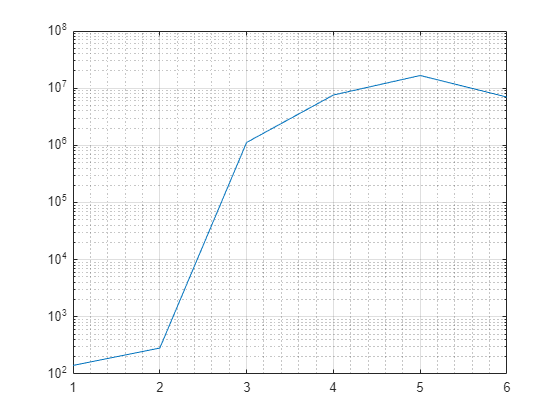

semilogy([p1,p2,p3,p4,p4_1,p4_2]),grid minor,grid on

%{
double(subs(phi,...
    [CSF, CWCC,D_w,    PR, c_a,    c_r,    h_C,  h_air,h_cham,mu, mu0,             r_A, r_Cout,r_cham,t_cfa,t_cfr, t_mba,t_mta,t_shell],...
    [0.75,10E6,0.26E-3,0.8,0.05E-3,0.05E-3,25E-3,1E-3, 1E-3,  850,1.25663706212E-6,5E-3,12E-3, 1E-3,  4E-3, 1.5E-3, 4E-3, 4E-3, 2E-3   ]))
double(subs(Fmag_1,...
    [CSF, CWCC,D_w,    PR, c_a,    c_r,    h_C,  h_air,h_cham,mu, mu0,             r_A, r_Cout,r_cham,t_cfa,t_cfr, t_mba,t_mta,t_shell],...
    [0.75,10E6,0.26E-3,0.8,0.05E-3,0.05E-3,25E-3,1E-3, 1E-3,  850,1.25663706212E-6,5E-3,12E-3, 1E-3,  4E-3, 1.5E-3, 4E-3, 4E-3, 2E-3   ]))
%}


L = N * phi / I

$$L = \begin{array}{l} \frac{{\mathrm{PR}}^{2}\,{h_{C}}^{2}\,{\left(c_{r}+r_{A}-r_{\mathrm{Cout}}+t_{\mathrm{cfr}}\right)}^{2}}{{D_{w}}^{4}\,\left(\frac{1}{\frac{\pi \,\mu_{0}\,{\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}}{h_{\mathrm{air}}}-\frac{\pi \,\mu_{0}\,\left(\frac{{h_{\mathrm{cham}}}^{2}}{{r_{\mathrm{cham}}}^{2}}+1\right)\,\left({\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}-{r_{A}}^{2}\right)}{h_{\mathrm{air}}}}+\frac{2}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi }+\frac{c_{a}}{\mu_{0}\,\pi \,\sigma_{1}}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{A}\right)}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{\mathrm{Cout}}\right)}+\frac{h_{C}-c_{a}+2\,t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}+t_{\mathrm{mta}}}{\mu \,\mu_{0}\,\pi \,\sigma_{1}}+\frac{c_{a}+\frac{h_{C}}{2}-h_{\mathrm{air}}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}}{\sigma_{2}}+\frac{c_{a}+\frac{h_{C}}{2}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mta}}}{2}}{\sigma_{2}}+\frac{t_{\mathrm{shell}}}{2\,\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{\mathrm{Cout}}+\frac{t_{\mathrm{shell}}}{2}\right)}-\frac{2\,\left(c_{r}+r_{A}-r_{\mathrm{Cout}}\right)}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{A}+r_{\mathrm{Cout}}\right)}+\frac{4\,r_{\mathrm{Cout}}}{\mu \,\mu_{0}\,t_{\mathrm{mta}}\,\pi \,\left(c_{a}+c_{r}+2\,r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}\right)}\\ \mathrm{where}\\ \sigma_{1}={\left(c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}^{2}-{\left(c_{r}+r_{\mathrm{Cout}}\right)}^{2}\\ \sigma_{2}=\mu \,\mu_{0}\,{r_{A}}^{2}\,\pi \end{array}$$

func_L = matlabFunction(L)

func_L = function_handle with value:
    @(D_w,PR,c_a,c_r,h_C,h_air,h_cham,mu,mu0,r_A,r_Cout,r_cham,t_cfa,t_cfr,t_mba,t_mta,t_shell)(1.0./D_w.^4.*PR.^2.*h_C.^2.*(c_r+r_A-r_Cout+t_cfr).^2)./(1.0./((mu0.*pi.*(r_A-r_cham).^2)./h_air-(mu0.*pi.*(h_cham.^2.*1.0./r_cham.^2+1.0).*((r_A-r_cham).^2-r_A.^2))./h_air)+2.0./(mu.*mu0.*t_mba.*pi)+c_a./(mu0.*pi.*((c_r+r_Cout+t_shell).^2-(c_r+r_Cout).^2))+c_r./(mu0.*t_mba.*pi.*(c_r./2.0+r_A))+c_r./(mu0.*t_mba.*pi.*(c_r./2.0+r_Cout))+(-c_a+h_C+t_cfa.*2.0+t_mba./2.0+t_mta)./(mu.*mu0.*pi.*((c_r+r_Cout+t_shell).^2-(c_r+r_Cout).^2))+(1.0./r_A.^2.*(c_a+h_C./2.0-h_air+t_cfa+t_mba./2.0))./(mu.*mu0.*pi)+(1.0./r_A.^2.*(c_a+h_C./2.0+t_cfa+t_mta./2.0))./(mu.*mu0.*pi)+t_shell./(mu.*mu0.*t_mba.*pi.*(c_r+r_Cout+t_shell./2.0).*2.0)-((c_r+r_A-r_Cout).*2.0)./(mu.*mu0.*t_mba.*pi.*(c_r+r_A+r_Cout))+(r_Cout.*4.0)./(mu.*mu0.*t_mta.*pi.*(c_a+c_r+r_Cout.*2.0+t_shell)))


syms rho % electrical resistivity of conductor
coil_length = pi * (r_Cout + r_Cin) * N

$$coil\_length = -\frac{\pi \,\mathrm{PR}\,h_{C}\,\left(c_{r}+r_{A}+r_{\mathrm{Cout}}+t_{\mathrm{cfr}}\right)\,\left(c_{r}+r_{A}-r_{\mathrm{Cout}}+t_{\mathrm{cfr}}\right)}{{D_{w}}^{2}}$$

func_coil_length = matlabFunction(coil_length)

func_coil_length = function_handle with value:
    @(D_w,PR,c_r,h_C,r_A,r_Cout,t_cfr)-1.0./D_w.^2.*PR.*h_C.*pi.*(c_r+r_A+r_Cout+t_cfr).*(c_r+r_A-r_Cout+t_cfr)


R = coil_length * rho / (pi * D_w^2 * 0.25)

$$R = -\frac{4\,\mathrm{PR}\,h_{C}\,\rho \,\left(c_{r}+r_{A}+r_{\mathrm{Cout}}+t_{\mathrm{cfr}}\right)\,\left(c_{r}+r_{A}-r_{\mathrm{Cout}}+t_{\mathrm{cfr}}\right)}{{D_{w}}^{4}}$$

func_R = matlabFunction(R)

func_R = function_handle with value:
    @(D_w,PR,c_r,h_C,r_A,r_Cout,rho,t_cfr)1.0./D_w.^4.*PR.*h_C.*rho.*(c_r+r_A+r_Cout+t_cfr).*(c_r+r_A-r_Cout+t_cfr).*-4.0


tao = L/R

$$tao = \begin{array}{l} -\frac{\mathrm{PR}\,h_{C}\,\left(c_{r}+r_{A}-r_{\mathrm{Cout}}+t_{\mathrm{cfr}}\right)}{4\,\rho \,\left(c_{r}+r_{A}+r_{\mathrm{Cout}}+t_{\mathrm{cfr}}\right)\,\left(\frac{1}{\frac{\pi \,\mu_{0}\,{\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}}{h_{\mathrm{air}}}-\frac{\pi \,\mu_{0}\,\left(\frac{{h_{\mathrm{cham}}}^{2}}{{r_{\mathrm{cham}}}^{2}}+1\right)\,\left({\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}-{r_{A}}^{2}\right)}{h_{\mathrm{air}}}}+\frac{2}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi }+\frac{c_{a}}{\mu_{0}\,\pi \,\sigma_{1}}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{A}\right)}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{\mathrm{Cout}}\right)}+\frac{h_{C}-c_{a}+2\,t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}+t_{\mathrm{mta}}}{\mu \,\mu_{0}\,\pi \,\sigma_{1}}+\frac{c_{a}+\frac{h_{C}}{2}-h_{\mathrm{air}}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}}{\sigma_{2}}+\frac{c_{a}+\frac{h_{C}}{2}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mta}}}{2}}{\sigma_{2}}+\frac{t_{\mathrm{shell}}}{2\,\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{\mathrm{Cout}}+\frac{t_{\mathrm{shell}}}{2}\right)}-\frac{2\,\left(c_{r}+r_{A}-r_{\mathrm{Cout}}\right)}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{A}+r_{\mathrm{Cout}}\right)}+\frac{4\,r_{\mathrm{Cout}}}{\mu \,\mu_{0}\,t_{\mathrm{mta}}\,\pi \,\left(c_{a}+c_{r}+2\,r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}\right)}\\ \mathrm{where}\\ \sigma_{1}={\left(c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}^{2}-{\left(c_{r}+r_{\mathrm{Cout}}\right)}^{2}\\ \sigma_{2}=\mu \,\mu_{0}\,{r_{A}}^{2}\,\pi \end{array}$$

func_tao = matlabFunction(tao)

func_tao = function_handle with value:
    @(PR,c_a,c_r,h_C,h_air,h_cham,mu,mu0,r_A,r_Cout,r_cham,rho,t_cfa,t_cfr,t_mba,t_mta,t_shell)(PR.*h_C.*(c_r+r_A-r_Cout+t_cfr).*(-1.0./4.0))./(rho.*(c_r+r_A+r_Cout+t_cfr).*(1.0./((mu0.*pi.*(r_A-r_cham).^2)./h_air-(mu0.*pi.*(h_cham.^2.*1.0./r_cham.^2+1.0).*((r_A-r_cham).^2-r_A.^2))./h_air)+2.0./(mu.*mu0.*t_mba.*pi)+c_a./(mu0.*pi.*((c_r+r_Cout+t_shell).^2-(c_r+r_Cout).^2))+c_r./(mu0.*t_mba.*pi.*(c_r./2.0+r_A))+c_r./(mu0.*t_mba.*pi.*(c_r./2.0+r_Cout))+(-c_a+h_C+t_cfa.*2.0+t_mba./2.0+t_mta)./(mu.*mu0.*pi.*((c_r+r_Cout+t_shell).^2-(c_r+r_Cout).^2))+(1.0./r_A.^2.*(c_a+h_C./2.0-h_air+t_cfa+t_mba./2.0))./(mu.*mu0.*pi)+(1.0./r_A.^2.*(c_a+h_C./2.0+t_cfa+t_mta./2.0))./(mu.*mu0.*pi)+t_shell./(mu.*mu0.*t_mba.*pi.*(c_r+r_Cout+t_shell./2.0).*2.0)-((c_r+r_A-r_Cout).*2.0)./(mu.*mu0.*t_mba.*pi.*(c_r+r_A+r_Cout))+(r_Cout.*4.0)./(mu.*mu0.*t_mta.*pi.*(c_a+c_r+r_Cout.*2.0+t_shell))))


%{
density6061 = 2700;
density430F = 7800;
densityCopper = 8960;
%}
%syms rho_insulator rho_permeable rho_conductor 

rho_insulator = 2700;
rho_permeable = 7800;
rho_conductor = 8960;

W_copper = pi * PR * h_C * (r_Cout^2 - r_Cin^2) * rho_conductor

$$W\_copper = -8960\,\pi \,\mathrm{PR}\,h_{C}\,\left({\left(c_{r}+r_{A}+t_{\mathrm{cfr}}\right)}^{2}-{r_{\mathrm{Cout}}}^{2}\right)$$

func_W_copper = matlabFunction(W_copper)

func_W_copper = function_handle with value:
    @(PR,c_r,h_C,r_A,r_Cout,t_cfr)PR.*h_C.*pi.*((c_r+r_A+t_cfr).^2-r_Cout.^2).*-8.96e+3


double(subs(W_copper,...
    [PR, c_r,    h_C,  r_A, r_Cout,rho_conductor,t_cfr],...
    [0.8,0.05E-3,50E-3,5E-3,15E-3, 8960,         1.5E-3]))

ans = 0.2050

%double(subs(W_copper,[PR,d2,d4,l4],[0.7,27E-3,8E-3,25E-3]))
W_coilformer = pi * (2 * t_cfa * (r_Cout^2 - r_A^2) + h_C * (r_Cin^2 - r_A^2))* rho_insulator

$$W\_coilformer = -2700\,\pi \,\left(2\,t_{\mathrm{cfa}}\,\left({r_{A}}^{2}-{r_{\mathrm{Cout}}}^{2}\right)-h_{C}\,\left({\left(c_{r}+r_{A}+t_{\mathrm{cfr}}\right)}^{2}-{r_{A}}^{2}\right)\right)$$

double(subs(W_coilformer,...
    [c_r,   h_C,  r_A, r_Cout,rho_insulator,t_cfa,t_cfr ],...
    [0.5E-3,50E-3,5E-3,15E-3, 2700,         5E-3, 1.5E-3]))

ans = 0.0271

W_shell = pi * ((r_Cout + t_shell)^2 - r_Cout^2) * (h_C + t_mba) * rho_permeable

$$W\_shell = 7800\,\pi \,\left({\left(r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}^{2}-{r_{\mathrm{Cout}}}^{2}\right)\,\left(h_{C}+t_{\mathrm{mba}}\right)$$

W_magtop = pi * (t_mta * (r_Cout^2 - r_A^2) + r_A^2 * (h_C / 2 + t_cfa) ) * rho_permeable

$$W\_magtop = -7800\,\pi \,\left(t_{\mathrm{mta}}\,\left({r_{A}}^{2}-{r_{\mathrm{Cout}}}^{2}\right)-{r_{A}}^{2}\,\left(\frac{h_{C}}{2}+t_{\mathrm{cfa}}\right)\right)$$

W_magbot = pi * (r_Cout^2 - r_A^2) * t_mba * rho_permeable

$$W\_magbot = -7800\,\pi \,t_{\mathrm{mba}}\,\left({r_{A}}^{2}-{r_{\mathrm{Cout}}}^{2}\right)$$

W_magArmature = pi * r_A^2 * (h_C / 2 + t_cfa) * rho_permeable

$$W\_magArmature = 7800\,\pi \,{r_{A}}^{2}\,\left(\frac{h_{C}}{2}+t_{\mathrm{cfa}}\right)$$

Weight = W_copper + W_coilformer + W_shell + W_magtop + W_magbot + W_magArmature

$$Weight = \begin{array}{l} 7800\,\pi \,{r_{A}}^{2}\,\left(\frac{h_{C}}{2}+t_{\mathrm{cfa}}\right)-2700\,\pi \,\left(2\,t_{\mathrm{cfa}}\,\sigma_{1}-h_{C}\,\left(\sigma_{2}-{r_{A}}^{2}\right)\right)-7800\,\pi \,\left(t_{\mathrm{mta}}\,\sigma_{1}-{r_{A}}^{2}\,\left(\frac{h_{C}}{2}+t_{\mathrm{cfa}}\right)\right)+7800\,\pi \,\left({\left(r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}^{2}-{r_{\mathrm{Cout}}}^{2}\right)\,\left(h_{C}+t_{\mathrm{mba}}\right)-7800\,\pi \,t_{\mathrm{mba}}\,\sigma_{1}-8960\,\pi \,\mathrm{PR}\,h_{C}\,\left(\sigma_{2}-{r_{\mathrm{Cout}}}^{2}\right)\\ \mathrm{where}\\ \sigma_{1}={r_{A}}^{2}-{r_{\mathrm{Cout}}}^{2}\\ \sigma_{2}={\left(c_{r}+r_{A}+t_{\mathrm{cfr}}\right)}^{2} \end{array}$$

double(subs(Weight,...
    [PR, c_r,    h_C,  r_A, r_Cout,rho_conductor,rho_insulator,rho_permeable,t_cfa,t_cfr, t_mba,t_mta,t_shell],...
    [0.8,0.05E-3,50E-3,5E-3,15E-3, 8960,         2700,         7800,         5E-3, 1.5E-3,5E-3, 5E-3, 2E-3]))

ans = 0.4016

%gradient(Weight)
func_weight = matlabFunction(Weight)

func_weight = function_handle with value:
    @(PR,c_r,h_C,r_A,r_Cout,t_cfa,t_cfr,t_mba,t_mta,t_shell)pi.*(t_mta.*(r_A.^2-r_Cout.^2)-r_A.^2.*(h_C./2.0+t_cfa)).*-7.8e+3-pi.*(t_cfa.*(r_A.^2-r_Cout.^2).*2.0-h_C.*((c_r+r_A+t_cfr).^2-r_A.^2)).*2.7e+3+r_A.^2.*pi.*(h_C./2.0+t_cfa).*7.8e+3+pi.*((r_Cout+t_shell).^2-r_Cout.^2).*(h_C+t_mba).*7.8e+3-t_mba.*pi.*(r_A.^2-r_Cout.^2).*7.8e+3-PR.*h_C.*pi.*((c_r+r_A+t_cfr).^2-r_Cout.^2).*8.96e+3


dPR

%dWeight_dcop = diff(Weight,PR)

## Test Case 1

- Infinite Upstream Volume @ 400 bar 273 K

- Pipe Section after upstream @ 400 bar 273 K

- Infinite Downstream Volume @ 1 bar 273 K

- Pipe Section before downstream @ 1 bar 273 K

- Outlet external orifice D = 2 mm

- Pilot closed @ t(0)

- P_ac = 400 bar @ t(0)

- Plunger displacement x = 0 @ t(0)

var_min_air_gap = 0.05E-3;
var_c_r = 0.1E-3;
var_c_a = 0.3E-3;
var_h_C = 50E-3;
var_r_Cout = 16.5E-3;
var_D_w = 0.27E-3;
var_t_cfr = 1.5E-3;
var_t_cfa = 5E-3;
var_t_mba = 5E-3;
var_t_mta = 5E-3;
var_r_A = 5E-3 - var_c_r;
var_r_cham = 2E-3;
var_h_cham = 2E-3;
var_t_shell = 2E-3;
var_PR = 0.8;
var_CSF = 0.85;

Nturns = 5.4870e+03

var_h_air = 0.3E-3;

ans = 396.4699

var_mu = 550;

resistance = 116.3328

var_mu0 = 1.25663706212E-6;

max_I = 0.4867

var_CWCC = 10E6;

ans = 2.6704e+03

var_erc = 1.68E-8; % ohm*m electrical_resistivity_of_copper

Vdd = 56.6159


Nturns = func_N(var_D_w,var_PR,var_c_r,var_h_C,var_r_A,var_r_Cout,var_t_cfr)
func_coil_length(var_D_w, var_PR, var_c_r, var_h_C, var_r_A, var_r_Cout, var_t_cfr)

tao_open = 0.1198

resistance = func_R(var_D_w,var_PR,var_c_r,var_h_C,var_r_A,var_r_Cout,var_erc,var_t_cfr)

tao_close = 0.1589

max_I = func_I_max(var_CSF,var_CWCC,var_D_w)

t_max = 278749

Nturns*max_I
Vdd = resistance * max_I

dt = 1e-6; % s
tao_open   = 3 * (Nturns^2/func_R_total(var_c_a,var_c_r,var_h_C,var_h_air,var_h_cham,var_mu,var_mu0,var_r_A,var_r_Cout,var_r_cham,var_t_cfa,var_t_mba,var_t_mta,var_t_shell))/resistance
tao_close  = 3 * (Nturns^2/func_R_total(var_c_a,var_c_r,var_h_C,var_min_air_gap,var_h_cham,var_mu,var_mu0,var_r_A,var_r_Cout,var_r_cham,var_t_cfa,var_t_mba,var_t_mta,var_t_shell))/resistance
t_max = ceil((tao_open+tao_close)/dt) % s
signal(1,1:t_max) = 0;
t(1,1:t_max) = (0:(t_max-1))*dt; % s

voltage(1,1:t_max) = Vdd;
voltage_L(1,1:t_max) = voltage(1);
current(1,1:t_max) = 0;
MR_total(1,1:t_max) = func_R_total(var_c_a,var_c_r,var_h_C,var_h_air,var_h_cham,var_mu,var_mu0,var_r_A,var_r_Cout,var_r_cham,var_t_cfa,var_t_mba,var_t_mta,var_t_shell);
flux(1,1:t_max) = 0;
inductance(1,1:t_max) = Nturns^2 / MR_total(1);
di_dt(1,1:t_max) = voltage_L(1) / inductance(1);
mag_flux_density_cham(1,1:t_max) = 0;
mag_flux_density_arm(1,1:t_max) = 0;
mag_flux_density_arm_cham(1,1:t_max) = 0;
mag_flux_density_shell(1,1:t_max) = 0;
mag_flux_density_limit(1,1:t_max) = 0;
mag_flux_density(1,1:t_max) = 0;
mag_field(1,1:t_max) = 0;


pilot(1,1:t_max) = 0; % 1 = open, 0 = closed

gam = 1.4;
R_gc = 296.8; % J/kgK
Cv = 0.743; % kJ/kg.K
polythropic_index = gam ;

P_U = B_to_Pa(50); %bar
T_U = 273; %K
P_D = B_to_Pa(1); %bar
T_D = 273; %K

P_u(1,1:t_max) = P_U; % bar
P_d(1,1:t_max) = P_D; % bar
P_cham(1,1:t_max) = P_u(1); % bar
P_airgap(1,1:t_max) = P_u(1); % bar

T_u(1,1:t_max) = T_U; % K
T_d(1,1:t_max) = T_D; % K
T_cham(1,1:t_max) = T_u(1); % K
T_airgap(1,1:t_max) = T_u(1); % K


x_pre = 5.0000e-04

m_dot_u_cham(1,1:t_max) = 0;
m_dot_cham_d(1,1:t_max) = 0;
m_dot_cham_airgap(1,1:t_max) = 0;
m_dot_cham_net(1,1:t_max) = 0;

x0 = 0; %m
x_pre = 0.5E-3 %m

W_armature = 0.0177

x(1,1:t_max) = x0; % m
v(1,1:t_max) = 0; % m/s
a(1,1:t_max) = 0; % m/s^2

Ks = 8000; % N/m
density430F = 7800;
W_armature = double(subs(W_magArmature,[h_C,r_A,rho_permeable,t_cfa],[var_h_C,var_r_A,density430F,var_t_cfa]))

func_V_airgap = function_handle with value:
    @(c_r,h_C,h_air,r_A)(h_C.*pi.*((c_r+r_A).^2-r_A.^2))./4.0+h_air.*pi.*(c_r+r_A).^2


%{

func_V_chamber = function_handle with value:
    @(c_r,h_C,h_air,r_A)(pi.*(c_r+r_A).^2)./2.0e+2+(h_C.*pi.*((c_r+r_A).^2-r_A.^2))./4.0-h_air.*r_A.^2.*pi


air gap and chamber volumes are depending on the armature displacement.
%}
r_outlet = 2 * var_h_air;
r_inlet =  r_outlet * sqrt(2);

func_V_airgap = matlabFunction(h_air * (r_A + c_r)^2 * pi + 0.25 * pi * h_C * ((r_A + c_r)^2 - r_A^2) )
func_V_chamber = matlabFunction(5E-3 * (r_A + c_r)^2 * pi - h_air * r_A^2 * pi + 0.25 * pi * h_C * ((r_A + c_r)^2 - r_A^2))
Vol_airgap(1,1:t_max) = func_V_airgap(var_c_r,var_h_C,var_h_air,var_r_A);
Vol_chamber(1,1:t_max) = func_V_chamber(var_c_r,var_h_C,var_h_air,var_r_A);

M_airgap(1,1:t_max) = P_airgap(1) * Vol_airgap(1) / (T_airgap(1) * R_gc);
M_cham(1,1:t_max) = P_cham(1) * Vol_chamber(1) / (T_cham(1) * R_gc);


Cd_inout = 0.6;
Cd_clearance = 0.5;

A_inlet = pi * r_inlet^2; % * Cd_inout;
A_outlet = pi * r_outlet^2; % * Cd_inout;

A_clearance = ((var_r_A + var_c_r)^2 - var_r_A^2 )* pi; % * Cd_clearance;

F_airgap(1,1:t_max) = P_airgap(1) * var_r_A^2 * pi;
F_cham(1,1:t_max) = P_cham(1) * (var_r_A^2-r_outlet^2) * pi;
F_spring(1,1:t_max) = (x_pre + x(1)) * Ks;
F_mag(1,1:t_max) = 0;
F(1,1:t_max) = - F_airgap(1) + F_cham(1) - F_spring(1);

load_b_h_430f;
f = waitbar(0, 'Starting');
tic
%try
for i = 2:t_max

    if mod(i,round(t_max/1000)) == 0
        waitbar(i/t_max, f, sprintf('Progress: %.1f %% - %.1f seconds elapsed.\n%.1f seconds projected - %.1f seconds remain.', i/t_max*100,toc,toc/(i/t_max),toc/(i/t_max)-toc));
    end
    
    signal(i) = t(i) < tao_open; % 1 = open, 0 = closed
    
    % Motion with last steps forces

    x(i) = checkImag(x(i-1) + v(i-1)*dt + 0.5*a(i-1)*dt^2); % m
    v(i) = checkImag(v(i-1) + a(i-1)*dt); % m/s
    a(i) = checkImag(F(i-1) / W_armature); % m/s^2
    if x(i) <= 0 && a(i) <= 0
        x(i) = 0; % m
        v(i) = 0; % m/s
        a(i) = 0; % m/s^2
    elseif (var_h_air - x(i)) <= var_min_air_gap && a(i) >= 0
        x(i) = var_h_air - var_min_air_gap; % m
        v(i) = 0; % m/s
        a(i) = 0; % m/s^2
    end

    % Old Design Magnetism
    current(i) = current(i-1) + di_dt(i-1) * dt;

    % flux(i) = func_phi(var_D_w,current(i),0.95,)
    MR_total(i) = func_R_total(var_c_a,var_c_r,var_h_C,var_h_air - x(i),var_h_cham,var_mu,var_mu0,var_r_A,var_r_Cout,var_r_cham,var_t_cfa,var_t_mba,var_t_mta,var_t_shell);
    flux(i) = Nturns * current(i) / MR_total(i);
    mag_field(i) = Nturns * current(i) / var_h_C;
    mag_flux_density_cham(i) = flux(i)/(pi * (var_r_A^2 - var_r_cham^2)/cos(atan(var_h_cham/var_r_cham)));
    mag_flux_density_arm(i) = flux(i)/(pi * (var_r_A - var_r_cham)^2);
    mag_flux_density_arm_cham(i) = flux(i)/(pi * var_r_A^2);
    mag_flux_density_shell(i) = flux(i)/(pi*((var_c_r+var_r_Cout+var_t_shell)^2-(var_c_r+var_r_Cout)^2));
    mag_flux_density_limit(i) = correctFlux(mag_field(i),bh430F);
    if max([mag_flux_density_arm_cham(i), mag_flux_density_shell(i)]) > mag_flux_density_limit(i)
        mag_flux_density(i) = mag_flux_density_limit(i);
    else
        mag_flux_density(i) = max([mag_flux_density_arm_cham(i), mag_flux_density_shell(i)]);
    end
    if current(i) ~= 0
        inductance(i) = Nturns * (mag_flux_density(i) * var_r_A^2 * pi) / current(i);
    else
        inductance(i) = Nturns^2 / MR_total(i)
    end
    F_mag(i) = 0.5 * (mag_flux_density(i)^2 * var_r_A^2 * pi) / var_mu0;
    if (signal(i) > 0)
        applied_V = Vdd;
    else
        applied_V = 0;
    end
    voltage_L(i) = applied_V - current(i) * resistance;
    di_dt(i) = voltage_L(i) / inductance(i) ;

    % Fluids
    Vol_airgap(i) = func_V_airgap(var_c_r,var_h_C,var_h_air - x(i),var_r_A);
    Vol_chamber(i) = func_V_chamber(var_c_r,var_h_C,var_h_air - x(i),var_r_A);
    
        % Adiabatic Compression
    [T_cham(i), P_cham(i)] = volChange(Vol_chamber(i-1),Vol_chamber(i),T_cham(i-1),P_cham(i-1),polythropic_index);

    [T_airgap(i), P_airgap(i)] = volChange(Vol_airgap(i-1),Vol_airgap(i),T_airgap(i-1),P_airgap(i-1),1);

        % Outlet Flow
    [P_cham(i),T_cham(i),M_cham(i),P_d(i),T_d(i),dummy,m_dot_cham_d(i)] = ...
        gasExchange(P_cham(i),T_cham(i),M_cham(i-1),Vol_chamber(i),P_D,T_D,inf,inf,gam,A_outlet*(x(i)/var_h_air),R_gc,Cv,dt,m_dot_cham_d(i-1));

    if P_cham(i)<P_airgap(i)
        ahgjhgjh =1;
    end
%gasExchange(P1,T1,M1,vol1,P2,T2,M2,vol2,gam,A,R,Cv,dt,mdot_old)
        % Inlet Flows
    [P_u(i),T_u(i),dummy,P_cham(i),T_cham(i),M_cham(i),m_dot_u_cham(i)] = ...
        gasExchange(P_U,T_U,inf,inf,P_cham(i),T_cham(i),M_cham(i),Vol_chamber(i),gam,A_inlet,R_gc,Cv,dt,m_dot_u_cham(i-1));

        % Internal Flow
    [P_cham(i),T_cham(i),M_cham(i),P_airgap(i),T_airgap(i),M_airgap(i),m_dot_cham_airgap(i)] = ...
        gasExchange(P_cham(i),T_cham(i),M_cham(i),Vol_chamber(i),P_airgap(i),T_airgap(i),M_airgap(i-1),Vol_airgap(i),gam,A_clearance,R_gc,Cv,dt,m_dot_cham_airgap(i-1));
    
    %M_airgap(i) = M_airgap(i-1);
    %m_dot_cham_airgap(i) = m_dot_cham_airgap(i-1);

    m_dot_cham_net(i) = m_dot_u_cham(i) - m_dot_cham_d(i) - m_dot_cham_airgap(i);
        %{
    [P_temp, T_temp, M_temp] = tank_discharge_io(...
        P_cham(i),T_cham(i),M_cham(i-1),...
        [T_U,     T_airgap(i), T_D],...
        [P_U,     P_airgap(i), P_D],...
        [A_inlet, A_clearance, A_outlet*(x(i)/var_h_air)],...
        gam,R_gc,dt); % bar, K, kg
    P_cham(i) = checkImag(P_temp);
    T_cham(i) = checkImag(T_temp);
    M_cham(i) = checkImag(M_temp);

    [P_temp, T_temp, M_temp] = tank_discharge_io(...
        P_airgap(i),T_airgap(i),M_airgap(i-1),...
        [T_cham(i)],...
        [P_cham(i)],...
        [A_clearance],...
        gam,R_gc,dt); % bar, K, kg

    P_airgap(i) = checkImag(P_temp);
    T_airgap(i) = checkImag(T_temp);
    M_airgap(i) = checkImag(M_temp);
        %}

    % Forces

    F_airgap(i) = P_airgap(i) * var_r_A^2 * pi;
    F_cham(i) = P_cham(i) * (var_r_A^2 - r_outlet^2) * pi;
    F_spring(i) = (x_pre + x(i)) * Ks;
    F(i) = checkImag(- F_airgap(i) + F_cham(i) - F_spring(i) + F_mag(i));

end
%{

Elapsed time is 19.743357 seconds.


catch
    errordlg('Imaginary number!','Computation Error');
    i
end
%}
close(f);
toc

% Reduce data size
if length(t) == t_max
    tic
    reduce_factor = 1000;
    pilot = downsample(movmean(pilot,reduce_factor),reduce_factor);
    signal = downsample(movmean(signal,reduce_factor),reduce_factor);
    t = downsample(t,reduce_factor);

    P_airgap = Pa_to_B(downsample(movmean(P_airgap,reduce_factor),reduce_factor));
    P_cham = Pa_to_B(downsample(movmean(P_cham,reduce_factor),reduce_factor));
    P_u = Pa_to_B(downsample(movmean(P_u,reduce_factor),reduce_factor));
    P_d = Pa_to_B(downsample(movmean(P_d,reduce_factor),reduce_factor));
    
    T_airgap = downsample(movmean(T_airgap,reduce_factor),reduce_factor);
    T_cham = downsample(movmean(T_cham,reduce_factor),reduce_factor);
    T_u = downsample(movmean(T_u,reduce_factor),reduce_factor);
    T_d = downsample(movmean(T_d,reduce_factor),reduce_factor);
    
    M_airgap = downsample(movmean(M_airgap,reduce_factor),reduce_factor);
    M_cham = downsample(movmean(M_cham,reduce_factor),reduce_factor);
    
    Vol_airgap = downsample(movmean(Vol_airgap,reduce_factor),reduce_factor);
    Vol_chamber = downsample(movmean(Vol_chamber,reduce_factor),reduce_factor);
    
    m_dot_cham_d = downsample(movmean(m_dot_cham_d,reduce_factor),reduce_factor);                               
    m_dot_cham_airgap = downsample(movmean(m_dot_cham_airgap,reduce_factor),reduce_factor);
    m_dot_u_cham = downsample(movmean(m_dot_u_cham,reduce_factor),reduce_factor);
    m_dot_cham_net = downsample(movmean(m_dot_cham_net,reduce_factor),reduce_factor);
    
    di_dt = downsample(movmean(di_dt,reduce_factor),reduce_factor);
    current = downsample(movmean(current,reduce_factor),reduce_factor);
    voltage_L = downsample(movmean(voltage_L,reduce_factor),reduce_factor);
    voltage = downsample(movmean(voltage,reduce_factor),reduce_factor);
    inductance = downsample(movmean(inductance,reduce_factor),reduce_factor);
    MR_total = downsample(movmean(MR_total,reduce_factor),reduce_factor);
    flux = downsample(movmean(flux,reduce_factor),reduce_factor);
    mag_field = downsample(movmean(mag_field,reduce_factor),reduce_factor);
    mag_flux_density = downsample(movmean(mag_flux_density,reduce_factor),reduce_factor);
    mag_flux_density_cham = downsample(movmean(mag_flux_density_cham,reduce_factor),reduce_factor);
    mag_flux_density_arm = downsample(movmean(mag_flux_density_arm,reduce_factor),reduce_factor);
    mag_flux_density_shell = downsample(movmean(mag_flux_density_shell,reduce_factor),reduce_factor);
    mag_flux_density_limit = downsample(movmean(mag_flux_density_limit,reduce_factor),reduce_factor);
    mag_flux_density_arm_cham = downsample(movmean(mag_flux_density_arm_cham,reduce_factor),reduce_factor);

    x = downsample(movmean(x,reduce_factor),reduce_factor);
    v = downsample(movmean(v,reduce_factor),reduce_factor);
    a = downsample(movmean(a,reduce_factor),reduce_factor);
    

Elapsed time is 0.052557 seconds.


    F = downsample(movmean(F,reduce_factor),reduce_factor);
    F_mag = downsample(movmean(F_mag,reduce_factor),reduce_factor);

orifice_openinig_t = 0.0060

    F_spring = downsample(movmean(F_spring,reduce_factor),reduce_factor);

orifice_closing_t = 0.0952

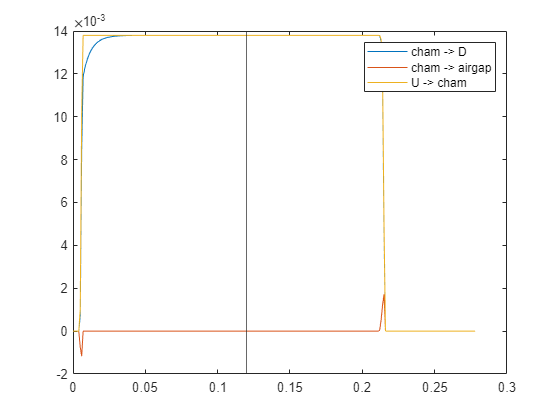

    F_cham = downsample(movmean(F_cham,reduce_factor),reduce_factor);
    F_airgap = downsample(movmean(F_airgap,reduce_factor),reduce_factor);
    toc
end

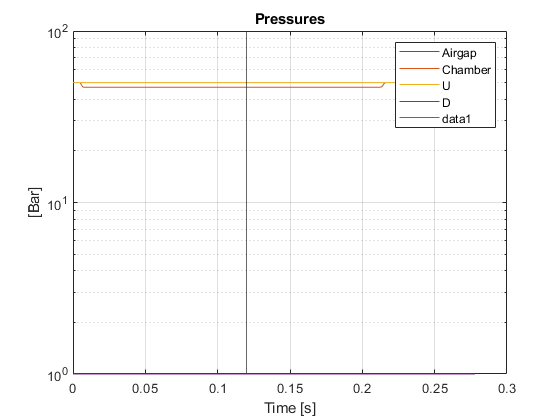

orifice_openinig_t = t(find(v == max(v),1))
orifice_closing_t = t(find(v == min(v),1)) - tao_open


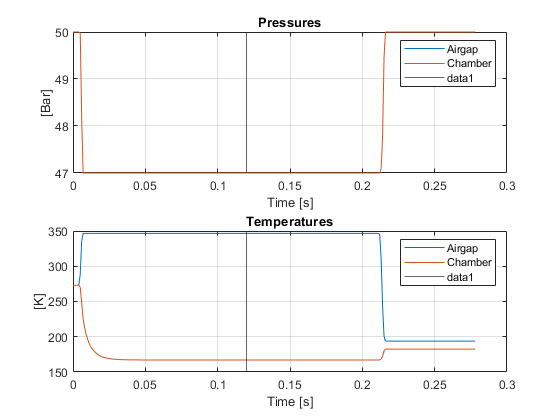

figure()
plot(t,m_dot_cham_d,t,m_dot_cham_airgap,t,m_dot_u_cham),xline(tao_open)
legend('cham -> D','cham -> airgap','U -> cham')

figure()
semilogy(t,P_airgap,t,P_cham,t,P_u,t,P_d),legend('Airgap','Chamber','U','D'),xline(tao_open)
title('Pressures'),grid on,xlabel('Time [s]'),ylabel('[Bar]')

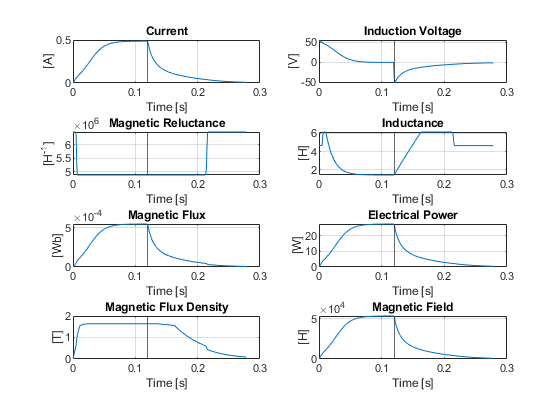

figure()
subplot(2,1,1)
plot(t,P_airgap,t,P_cham),legend('Airgap','Chamber'),xline(tao_open)
title('Pressures'),grid on,xlabel('Time [s]'),ylabel('[Bar]')
subplot(2,1,2)
plot(t,T_airgap,t,T_cham),legend('Airgap','Chamber'),xline(tao_open)
title('Temperatures'),grid on,xlabel('Time [s]'),ylabel('[K]')
figure() 
subplot(4,2,1)
plot(t,current),xline(tao_open)
title('Current'),grid on,xlabel('Time [s]'),ylabel('[A]')
subplot(4,2,2)
plot(t,voltage_L),xline(tao_open)
title('Induction Voltage'),grid on,xlabel('Time [s]'),ylabel('[V]')
subplot(4,2,3)
plot(t,MR_total),xline(tao_open)
title('Magnetic Reluctance'),grid on,xlabel('Time [s]'),ylabel('[H^{-1}]')
subplot(4,2,4)
plot(t,inductance),xline(tao_open)
title('Inductance'),grid on,xlabel('Time [s]'),ylabel('[H]')
subplot(4,2,5)
plot(t,flux),xline(tao_open)
title('Magnetic Flux'),grid on,xlabel('Time [s]'),ylabel('[Wb]')
subplot(4,2,6)
plot(t,current.*Vdd),xline(tao_open)

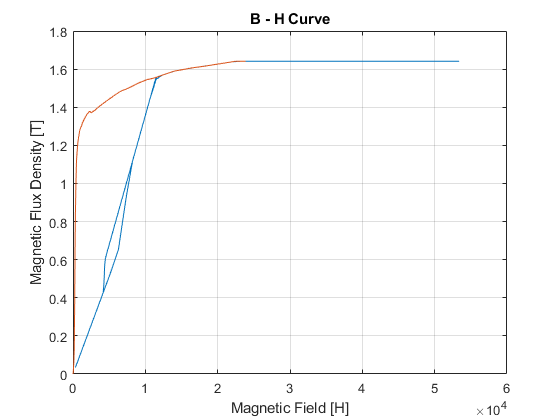

title('Electrical Power'),grid on,xlabel('Time [s]'),ylabel('[W]')
subplot(4,2,7)
plot(t,mag_flux_density),xline(tao_open)
title('Magnetic Flux Density'),grid on,xlabel('Time [s]'),ylabel('[T]')

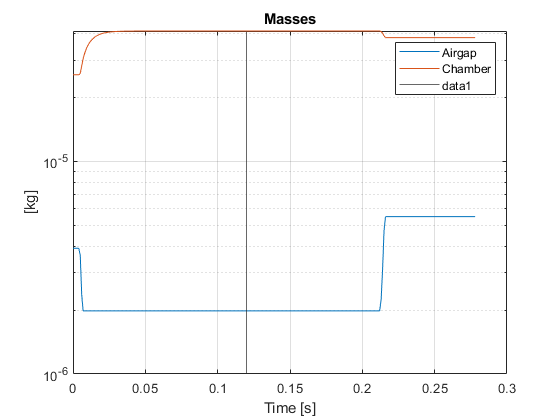

subplot(4,2,8)
plot(t,mag_field),xline(tao_open)
title('Magnetic Field'),grid on,xlabel('Time [s]'),ylabel('[H]')

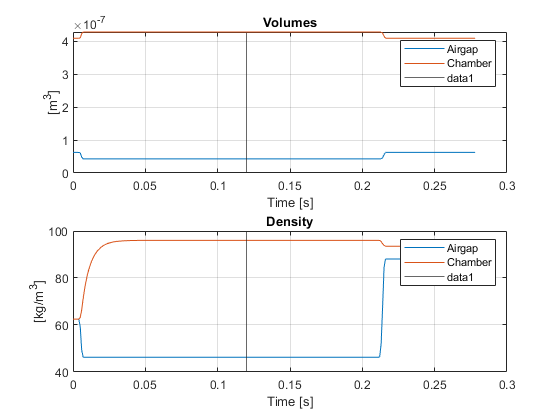

load_b_h_430f;
figure()
plot(mag_field,mag_flux_density,bh430F.H_Oe*1E3/(4*pi),bh430F.B_Gauss/1E4)
title('B - H Curve'),grid on,xlabel('Magnetic Field [H]'),ylabel('Magnetic Flux Density [T]')
figure()
semilogy(t,M_airgap,t,M_cham),legend('Airgap','Chamber'),xline(tao_open)
title('Masses'),grid on,xlabel('Time [s]'),ylabel('[kg]')

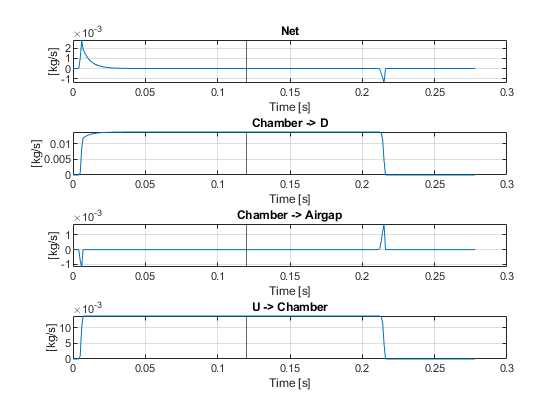

figure()
subplot(2,1,1)
plot(t,Vol_airgap,t,Vol_chamber),legend('Airgap','Chamber'),xline(tao_open)
title('Volumes'),grid on,xlabel('Time [s]'),ylabel('[m^3]')
subplot(2,1,2)
plot(t,M_airgap./Vol_airgap,t,M_cham./Vol_chamber),legend('Airgap','Chamber'),xline(tao_open)
title('Density'), grid on,xlabel('Time [s]'),ylabel('[kg/m^3]')
figure()
subplot(4,1,1)

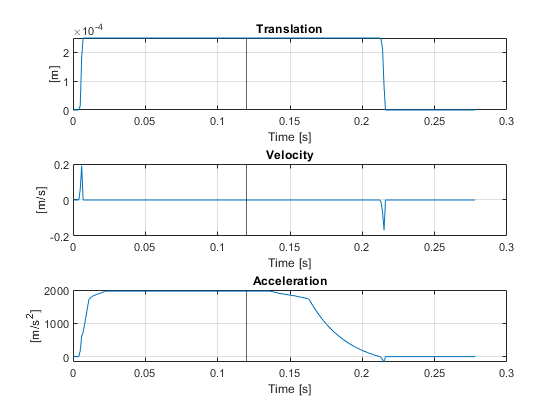

plot(t,m_dot_cham_net),title('Net'),grid on,xlabel('Time [s]'),ylabel('[kg/s]'),xline(tao_open)
subplot(4,1,2)
plot(t,m_dot_cham_d),title('Chamber -> D'),grid on,xlabel('Time [s]'),ylabel('[kg/s]'),xline(tao_open)
subplot(4,1,3)
plot(t,m_dot_cham_airgap),title('Chamber -> Airgap'),grid on,xlabel('Time [s]'),ylabel('[kg/s]'),xline(tao_open)
subplot(4,1,4)
plot(t,m_dot_u_cham),title('U -> Chamber'),grid on,xlabel('Time [s]'),ylabel('[kg/s]'),xline(tao_open)
figure()
subplot(3,1,1)
plot(t,x)

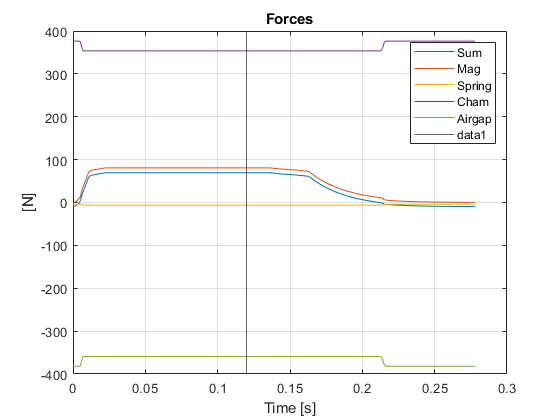

title('Translation'),grid on,xlabel('Time [s]'),ylabel('[m]'),xline(tao_open)
subplot(3,1,2)
plot(t,v)

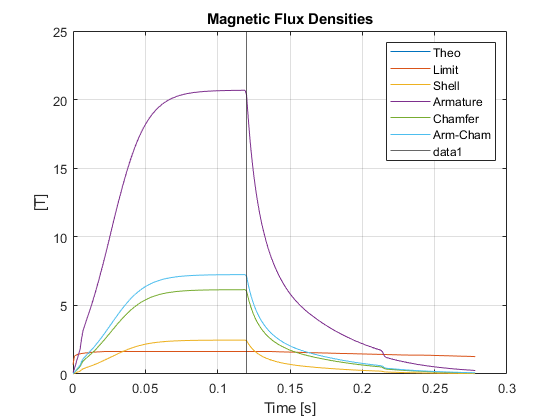

title('Velocity'),grid on,xlabel('Time [s]'),ylabel('[m/s]'),xline(tao_open)
subplot(3,1,3)
plot(t,a)

title('Acceleration'),grid on,xlabel('Time [s]'),ylabel('[m/s^2]'),xline(tao_open)
figure()
plot(t,F,t,F_mag,t,-F_spring,t,F_cham,t,-F_airgap),legend('Sum','Mag','Spring','Cham','Airgap'),xline(tao_open)

T_tension_test = 19951

title('Forces'),grid on,xlabel('Time [s]'),ylabel('[N]')
figure()
plot(t,mag_flux_density,t,mag_flux_density_limit,t,mag_flux_density_shell,t,mag_flux_density_arm,t,mag_flux_density_cham,t,mag_flux_density_arm_cham),legend('Theo','Limit','Shell','Armature','Chamfer','Arm-Cham'),xline(tao_open)
title('Magnetic Flux Densities'),grid on,xlabel('Time [s]'),ylabel('[T]')

x_tension_test = var_min_air_gap:1e-6:20e-3;
T_tension_test = length(x_tension_test)
tenstion_test_I = max_I;
tenstion_test_mag_field = Nturns * tenstion_test_I / var_h_C;
tenstion_test_mag_flux_density_max_limit = correctFlux(tenstion_test_mag_field,bh430F);
tic;
for i = 1:T_tension_test

    % flux(i) = func_phi(var_D_w,current(i),0.95,)
    tenstion_test_MR_total(i) = func_R_total(2*var_c_a,2*var_c_r,var_h_C,x_tension_test(i),var_h_cham,var_mu,var_mu0,var_r_A,var_r_Cout,var_r_cham,var_t_cfa,var_t_mba,var_t_mta,var_t_shell);
    tenstion_test_flux(i) = Nturns * tenstion_test_I / tenstion_test_MR_total(i);
    tenstion_test_mag_flux_density_cham(i) = tenstion_test_flux(i)/(pi * (var_r_A^2 - var_r_cham^2)/cos(atan(var_h_cham/var_r_cham)));
    tenstion_test_mag_flux_density_arm(i) = tenstion_test_flux(i)/(pi * (var_r_A - var_r_cham)^2);
    tenstion_test_mag_flux_density_arm_cham(i) = tenstion_test_flux(i)/(pi * var_r_A^2);
    tenstion_test_mag_flux_density_shell(i) = tenstion_test_flux(i)/(pi*((var_c_r+var_r_Cout+var_t_shell)^2-(var_c_r+var_r_Cout)^2));
    if max([tenstion_test_mag_flux_density_arm_cham(i), tenstion_test_mag_flux_density_arm(i), tenstion_test_mag_flux_density_shell(i)]) > tenstion_test_mag_flux_density_max_limit
        tenstion_test_mag_flux_density(i) = tenstion_test_mag_flux_density_max_limit;
    else

Elapsed time is 0.019519 seconds.


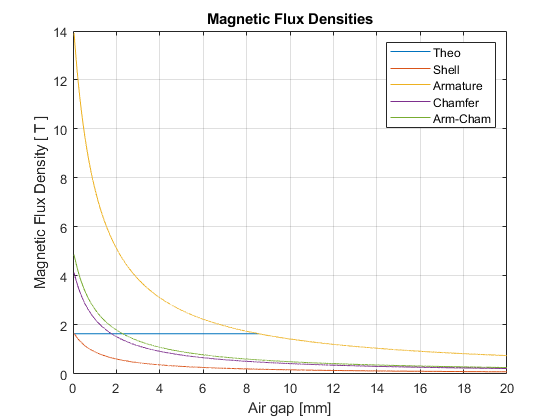

        tenstion_test_mag_flux_density(i) = max([tenstion_test_mag_flux_density_arm_cham(i), tenstion_test_mag_flux_density_shell(i), tenstion_test_mag_flux_density_arm(i)]);
    end
    tenstion_test_inductance(i) = Nturns * (tenstion_test_mag_flux_density(i) * var_r_A^2 * pi) / tenstion_test_I;
    tenstion_test_F_mag(i) = 0.5 * (tenstion_test_mag_flux_density(i)^2 * var_r_A^2 * pi) / var_mu0;

end
toc

figure()
plot(...

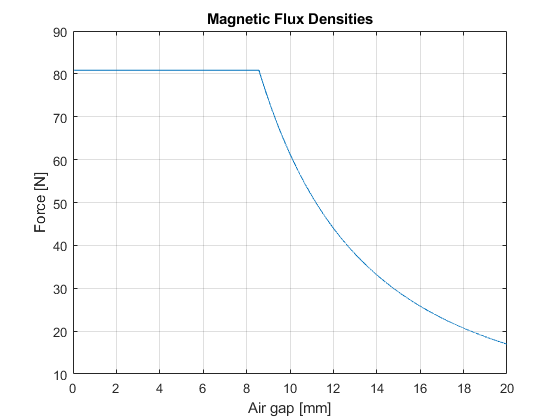

    x_tension_test*1e3,tenstion_test_mag_flux_density,...
    x_tension_test*1e3,tenstion_test_mag_flux_density_shell,...
    x_tension_test*1e3,tenstion_test_mag_flux_density_arm,...

    x_tension_test*1e3,tenstion_test_mag_flux_density_cham,...
    x_tension_test*1e3,tenstion_test_mag_flux_density_arm_cham...

optimize = 0

    ),legend('Theo','Shell','Armature','Chamfer','Arm-Cham')
title('Magnetic Flux Densities'),grid on,xlabel('Air gap [mm]'),ylabel('Magnetic Flux Density [ T ]')
figure()
plot(x_tension_test*1e3,tenstion_test_F_mag)
title('Magnetic Flux Densities'),grid on,xlabel('Air gap [mm]'),ylabel('Force [N]')

optimize = 0
if optimize
Fmag_gradient = gradient(Fmag);
symvar(Fmag)

func_Fmag_gradient = arrayfun(@(x) matlabFunction(x),Fmag_gradient,'UniformOutput', false)

tic
dummy = subs_Fmag_gradient(func_Fmag_gradient, var_D_w, max_I, var_PR, var_c_a, var_c_r, var_h_C, var_h_air, var_h_cham, var_mu, var_mu0, var_r_A, var_r_Cout, var_r_cham, var_t_cfa, var_t_cfr, var_t_mba, var_t_mta, var_t_shell)
toc
figure()
semilogy(abs(dummy))
grid on, grid minor

FORCE_GOAL = 10;
objective = sigmoid(2*Fmag/FORCE_GOAL) + sigmoid(func_weight(var_PR, var_c_r, var_h_C, var_r_A, var_r_Cout, var_t_cfa, var_t_cfr, var_t_mba, var_t_mta, var_t_shell)/Weight);
%objective = 2 * Fmag/FORCE_GOAL - Weight/func_weight(var_PR, var_c_r, var_h_C, var_r_A, var_r_Cout, var_t_cfa, var_t_cfr, var_t_mba, var_t_mta, var_t_shell);
symvar(objective);
func_objective = matlabFunction(objective);
objective_gradient = gradient(objective);
symvar(objective);

func_objective_gradient = arrayfun(@(x) matlabFunction(x),objective_gradient,'UniformOutput', false);
func_Fmag(var_D_w, max_I, var_PR, var_c_a, var_c_r, var_h_C, var_h_air, var_h_cham, var_mu, var_mu0, var_r_A, var_r_Cout, var_r_cham, var_t_cfa, var_t_cfr, var_t_mba, var_t_mta, var_t_shell)

func_weight(var_PR, var_c_r, var_h_C, var_r_A, var_r_Cout, var_t_cfa, var_t_cfr, var_t_mba, var_t_mta, var_t_shell)

optimized_params = optimize_valve(0, 0, func_objective, func_objective_gradient, var_D_w, max_I, var_PR, var_c_a, var_c_r, var_h_C, var_h_air, var_h_cham, var_mu, var_mu0, var_r_A, var_r_Cout, var_r_cham, var_t_cfa, var_t_cfr, var_t_mba, var_t_mta, var_t_shell);
plot(optimized_params(:,1))
temp = num2cell(optimized_params(1,2:end))
func_Fmag(temp{:}) 
temp = num2cell(optimized_params(end,2:end))
func_Fmag(temp{:}) 
find(optimized_params == max(optimized_params(:,1)))
temp = num2cell(optimized_params(find(optimized_params == max(optimized_params(:,1))),2:end))
func_Fmag(temp{1,:}) 
func_weight(temp{3},temp{5},temp{6},temp{11},temp{12},temp{14:end})
func_phi(temp{:})

clear forces weights
for i=1:length(optimized_params)
    temp = num2cell(optimized_params(i,2:end));
    forces(i) = func_Fmag(temp{:});
    weights(i) = func_weight(temp{3},temp{5},temp{6},temp{11},temp{12},temp{14:end});
end
target_index = find(min(abs(forces-FORCE_GOAL)) == abs(forces-FORCE_GOAL))
xlswrite('params.xlsx',[strcat('var_',string(symvar(Fmag)));double(optimized_params(target_index,2:end));strings([1,length(symvar(Fmag))])+'m']')
forces(target_index)

figure()
plot(weights*1E3,forces)
hold on
plot(weights(target_index)*1E3,forces(target_index),weights(1)*1E3,forces(1),"LineStyle",'none','Marker','+','MarkerSize',10,'LineWidth',3)
hold off
xlabel('Weight [g]'),ylabel('Force [N]'), title('Possible Designs')
grid on, grid minor
figure()
plot(func_weight(var_PR, var_c_r, var_h_C, var_r_A, var_r_Cout, var_t_cfa, var_t_cfr, var_t_mba, var_t_mta, var_t_shell)./weights,forces/FORCE_GOAL)
xlabel('Reference Weight/Weight'),ylabel('Force/Minimum Target Force'), title('Pareto Front')
grid on, grid minor
figure()
plot(1./sigmoid(weights/func_weight(var_PR, var_c_r, var_h_C, var_r_A, var_r_Cout, var_t_cfa, var_t_cfr, var_t_mba, var_t_mta, var_t_shell)),sigmoid(forces/FORCE_GOAL))
xlabel('1/Sigmoid(Weight/Reference Weight)'),ylabel('Sigmoid(Force/Minimum Target Force)'), title('Pareto Front')
grid on, grid minor
end

function result = subs_Fmag_gradient(func_Fmag_gradient,D_w, I, PR, c_a, c_r, h_C, h_air, h_cham, mu, mu0, r_A, r_Cout, r_cham, t_cfa, t_cfr, t_mba, t_mta, t_shell)
    result = cell2mat(cellfun(@(x) x(D_w, I, PR, c_a, c_r, h_C, h_air, h_cham, mu, mu0, r_A, r_Cout, r_cham, t_cfa, t_cfr, t_mba, t_mta, t_shell), func_Fmag_gradient,'UniformOutput', false))';
    %for i=1:length(func_Fmag_gradient)
    %    result(i) = func_Fmag_gradient{i}(D_w, I, PR, c_a, c_r, h_C, h_air, h_cham, mu, mu0, r_A, r_Cout, r_cham, t_cfa, t_cfr, t_mba, t_mta, t_shell);
    %end
end

function result = optimize_valve(last_max, repetition, func_F, func_F_gradient,D_w, I, PR, c_a, c_r, h_C, h_air, h_cham, mu, mu0, r_A, r_Cout, r_cham, t_cfa, t_cfr, t_mba, t_mta, t_shell)
    params =     [D_w,     I, PR,   c_a,     c_r,     h_C,   h_air, h_cham, mu, mu0, r_A,  r_Cout, r_cham, t_cfa, t_cfr, t_mba, t_mta, t_shell];
    lowLimits =  [0.27E-3, I, 0.5,  0.05E-3, 0.05E-3, 5E-3,  1E-3,  0.1E-3, mu, mu0, 1E-3, 6E-3,   1E-3,   4E-3,  1E-3,  1E-3,  1E-3,  1E-3];
    highLimits = [1E-3,    I, 0.95, 0.25E-3, 0.25E-3, 90E-3, 1E-3,  4E-3,   mu, mu0, 5E-3, 16E-3,  r_A,    10E-3  2E-3,  10E-3, 10E-3, 10E-3];

    r = func_F(D_w, I, PR, c_a, c_r, h_C, h_air, h_cham, mu, mu0, r_A, r_Cout, r_cham, t_cfa, t_cfr, t_mba, t_mta, t_shell);

    result = [r,params];

    for j=1:1000
        stepSize =   (highLimits - lowLimits) * 1E-3; %[0.1E-3,  0, 0.05, 0.05E-3, 0.05E-3, 1E-3,  0,    0.1E-3, 0,  0,   0.1E-3, 0.1E-3, 0.1E-3, 0.1E-3, 0.1E-3, 0.1E-3, 0.1E-3, 0.1E-3];
        grad = subs_Fmag_gradient(func_F_gradient,D_w, I, PR, c_a, c_r, h_C, h_air, h_cham, mu, mu0, r_A, r_Cout, r_cham, t_cfa, t_cfr, t_mba, t_mta, t_shell);
        for i=1:length(params)
            params(i) = params(i) + sign(grad(i)) * stepSize(i);
            if params(i) < lowLimits(i)
                params(i) = lowLimits(i);
            elseif params(i) > highLimits(i)
                params(i) = highLimits(i);
            end
        end
        %{
        if params(13) + 1E-3 > params(11)
            % impossible geometry
            params(11) = params(13) + 1E-3;
            if params(11) > highLimits(11)
                params(11) = highLimits(11);
                params(13) = params(11) - 1E-3;
            end
        end
        %}
        temp = num2cell(params);
        r = func_F(temp{:});
        if norm(result(end,:) - [r, params]) == 0
            break;
        end
        result = [result; r,params];
    end
    %{
    %params
    %(params - [D_w, I, PR, c_a, c_r, h_C, h_air, h_cham, mu, mu0, r_A, r_Cout, r_cham, t_cfa, t_cfr, t_mba, t_mta, t_shell])./stepSize
    if isequal(params,[D_w, I, PR, c_a, c_r, h_C, h_air, h_cham, mu, mu0, r_A, r_Cout, r_cham, t_cfa, t_cfr, t_mba, t_mta, t_shell]) || repetition == 4
        result = [D_w, I, PR, c_a, c_r, h_C, h_air, h_cham, mu, mu0, r_A, r_Cout, r_cham, t_cfa, t_cfr, t_mba, t_mta, t_shell];
    else
        temp = num2cell(params);
        if last_max == r
            repetition = repetition + 1;
        end
        last_max = max(last_max,r);
        result = optimize_valve(last_max, repetition, func_Fmag, func_Fmag_gradient, temp{:});
    end
    %}
end














